# Computer Arithmetic

Computers have an intersting way of performing arithmetic operations, and this is limited by the configuration of the computer. Computers represent non-integers as *floating point* numbers, i.e. as decimals, but because they have a finite amount of memory in which to store a number, these numbers usually have to be truncated or rounded up or down. This leads to an inaccuracy in the performing calculations. For example, let's calculate $(\sqrt{2})^2 - 2$, whcih should equal zero. 

x = 2.0;
x = (x^(1/2))^2 - x;
disp(['The value is '  num2str(x)])

The value is 4.4409e-16


The value of this number is not zero, though it is very small. In fact, it's so small that we might think there is no real problem. However, that is not the case. The reason is that computers are very good at doring very large numbers of calculations. If each of those calculations results in a small error because of the round off, then that erorr can accumluate. 

To see a dramatic example of this, consder the simple equation 


$$g(x) = -0.2x^2 + 1.4x + c$$


This has a nice property that $g(-3) = -3$. Let's see what happens if we keep repeating this calculation over and over, using the output from one calculation as the input for the next. 

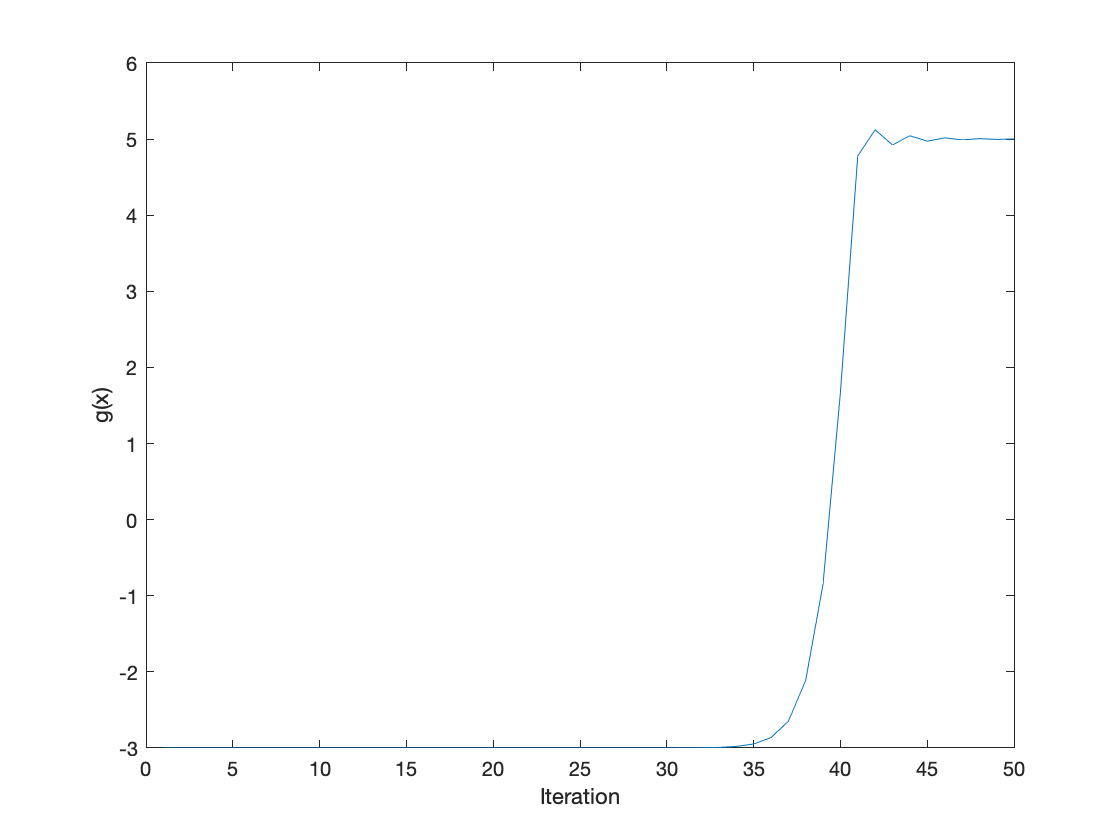

a = -0.2;
b = 1.4;
c = 3;

% Specifity the number of times we want to perform the calculation
n_loop = 50;

% Set some storage and set the initial value.
z = zeros(n_loop,1);
z(1) = -3.0;

% Perform the loop. 
for i_loop = 2 : n_loop
    z(i_loop) = a*z(i_loop-1)^2 + b*z(i_loop-1) + c;
end

% Plot the results. 
figure
plot([1:n_loop], z)
xlabel('Iteration')
ylabel('g(x)')

Something rather remarkable has happened. The value of $g(x)$ remains at or close to a value of -3 for about 32 iterations of the calculation, and then it starts to move away from that value and rapidly ends up at +5. The reason it arrives at this value is that $g(5) = 5$as well — in fact it is an attractor of the iterative mapping. 

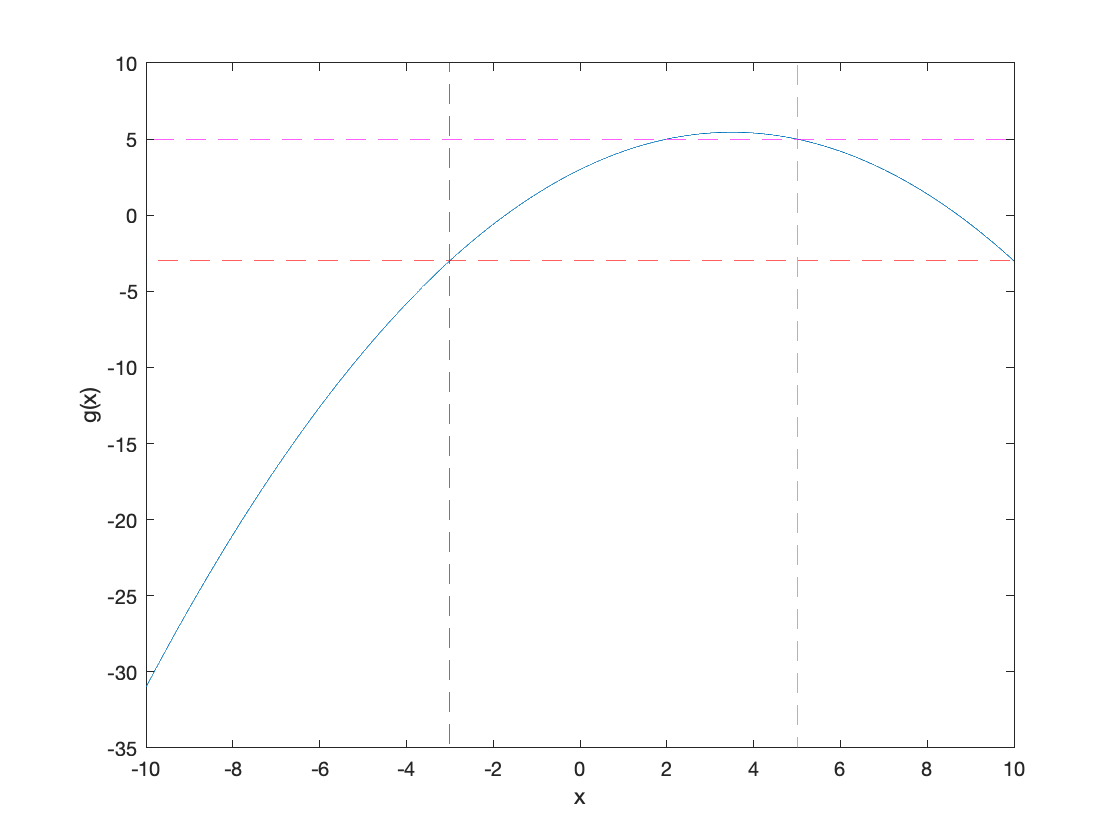

x = -10 : 0.01 : 10;
g = a*x.*x + b*x + c;
y = [-35 : 0.1 : 10];
figure
plot(x,g, x, -3*ones(size(x)), 'r--', x, 5*ones(size(x)), 'm--', -3*ones(size(y)), y, 'r--', 5*ones(size(y)), y, 'm--')
xlabel('x')
ylabel('g(x)')

So we can see that round off can become a big problem. In fact we can see that it becomes a problem right from the start by typing out the values of `z` for the first 10 iterations (we have changed the number of decimal places that the output shows).

format long e
z(1:10)

ans =     -3.000000000000000e+00
    -2.999999999999999e+00
    -2.999999999999997e+00
    -2.999999999999993e+00
    -2.999999999999981e+00
    -2.999999999999951e+00
    -2.999999999999873e+00
    -2.999999999999670e+00
    -2.999999999999141e+00
    -2.999999999997767e+00


We can see from this that the roundoff error is making itself felt from the first iteration onwards. 

However, we have deliberately made our problem worse in the above example. It is easy to calculate integer powers of numbers such as $x^{10}$ or $x^3$ by repeatedly multplying $x$ by itself. Calculating $x^{1/3}$, for example, is much harder and computers perform this calculation by using series expansions and doing this involves a lot of calculations. The hat operator, `^`, tells Matlab to use this second way of calculating the power, even if the power is an integer. So, we can reduce the problem of round off by not using the hat operator and just multiplying $x$ by itself. 

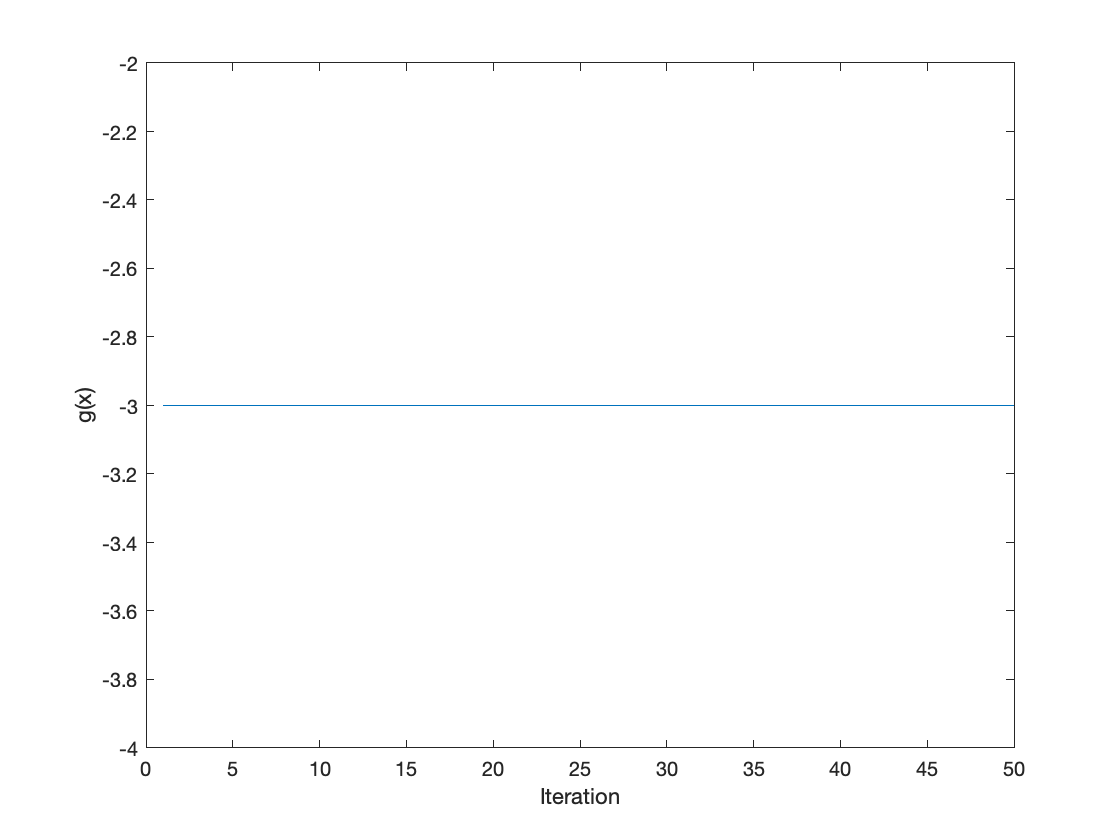

a = -0.2;
b = 1.4;
c = 3;

n_loop = 50;

z = zeros(n_loop,1);
z(1) = -3.0;

for i_loop = 2 : n_loop
    z(i_loop) = a*z(i_loop-1)*z(i_loop-1) + b*z(i_loop-1) + c;
end
figure
plot([1:n_loop], z)
xlabel('Iteration')
ylabel('g(x)')

We can see that the value now does not change, and we can look again at the values of the calculation.


format long e
z(1:10)

ans =     -3
    -3
    -3
    -3
    -3
    -3
    -3
    -3
    -3
    -3


Now we see that the value is stable and that the results of the calculation are what we expect. 

Numerical round off is not something that we should always be worried about, but it is something that we should take care to minimize, and we should keep it in mind especially if our computer codes start giving strange, apparently inexplicable results. 